# Average Electricity Usage in 1990 and 2019

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

electricity = readtable("../data/electricity.csv"); 

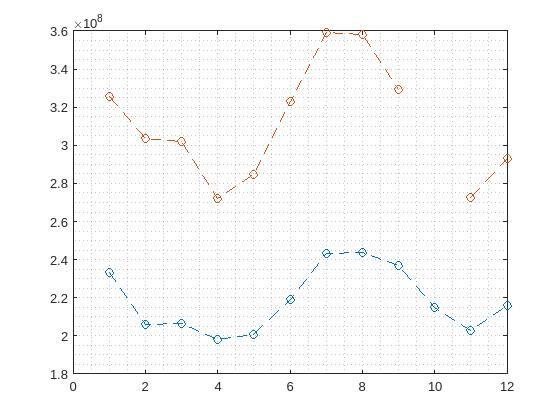

electricity = electricity(1:find(electricity.Date=='12/01/2015'), :);
com = reshape(electricity.Commercial, 12, []);
res = reshape(electricity.Residential, 12, []);
ind = reshape(electricity.Industrial, 12, []);

usage = ind + res + com;
firstYear = usage(:, 1);
lastYear = usage(:, end);
plot(1:12, firstYear, "o--")
grid minor
hold on
plot(1:12, lastYear, "o--")
hold off

## Task 1

avg1990 = mean(firstYear)

avg1990 = 2.1838e+08

avg2015 = mean(lastYear)

avg2015 = NaN

## Task 2

missing2019 = isnan(lastYear)

missing2019 = 12×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1


## Task 3

numNaNs = nnz(missing2019);

## Task 4

avg2015 = mean(lastYear, "omitnan")

avg2015 = 3.1128e+08

## Further Practice